warning off

params.Tau = 10.00;
params.TauR = 10.00;
params.gc = 9.00;
params.NaX = 0.70;
params.alpha = 10.00;
params.b = 1.00;

% Soma parameters
paramsSoma = params;
paramsSoma.NaX = 1; % Always 1

% Initial conditions
initCon = [0.02; 0.02];

soma = Dendrite(0, paramsSoma, initCon);                     
dendrite = Dendrite(0, params, initCon);                     

% dendritic tree model                                       
tree = DendriteTreeModel();                          

% Add soma                                                   
tree.addDendrite(soma);               

%Add dendrites                                              
% for i=1:1                                                   
%     dendrite.ID = i;
%     dendrite.params.NaX=0.01*i;
%     tree.addDendrite(dendrite);       
% end                                                          

%Define connections                                         
% tree.addConnectionStr("0-1");     

fs = 64e+3;
h = 1/fs;
tmax = 1;

freq_range = linspace(1, 3, 200);
amp_range = linspace(.5, 5, 60);

t = 0:h:tmax;

x_data = []; y_data = [];

tic
for i = 1 : numel(freq_range)
    f = freq_range(i);
    sig = 1 * sin(2 * pi* f*t);    
    tree.addStimuli(0, sig);
    [~, sol] = treeSolver(tree, tmax, h);

    [pks, ~] = findpeaks(sol(1, 1e+3:end), MinPeakHeight=0.6);

    x_data = [x_data; repmat(freq_range(i), numel(pks), 1)];
    y_data = [y_data, pks];
end
toc

Elapsed time is 20.592640 seconds.


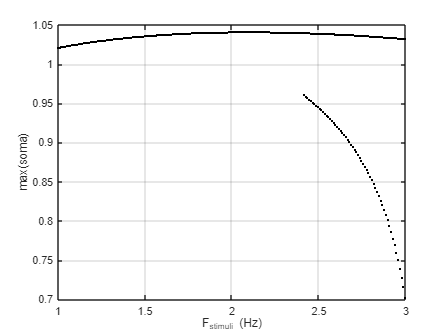


% c_data = zeros(numel(freq_range), numel(amp_range));
% 
% tic
% for i = 1 : numel(freq_range)
%     for j = 1 : numel(amp_range)
%         f = freq_range(i);
%         A = amp_range(j);
%         sig = A*sin(2*pi*f*t);    
%         tree.addStimuli(0, sig);
%         [~, sol] = treeSolver(tree, tmax, h);
% 
%         [pks, ~] = findpeaks(sol(1, :));
%         CC = dbscan(pks', 1e-6, 1);
% 
%         c_data(i, j) = max(CC);
%     end
% end
% toc

% figure
% imagesc(freq_range, amp_range, c_data);
% set(gca, 'YDir', 'normal');
% xlabel('F (Hz)')
% ylabel('A')
% colorbar

figure;
plot(x_data, y_data, '.k');
grid on
xlabel('F_{stimuli} (Hz)')
ylabel('max(soma)');